clear;
clc;

# Part 1

Fnoa = [ 1 0 0 2;
         0 1 0 3;
         0 0 1 4;
         0 0 0 1]

Fnoa =      1     0     0     2
     0     1     0     3
     0     0     1     4
     0     0     0     1



Translate = [ 1 0 0 -2;
              0 1 0 1;
              0 0 1 -2;
              0 0 0 1]

Translate =      1     0     0    -2
     0     1     0     1
     0     0     1    -2
     0     0     0     1



Fnew = Translate * Fnoa

Fnew =      1     0     0     0
     0     1     0     4
     0     0     1     2
     0     0     0     1


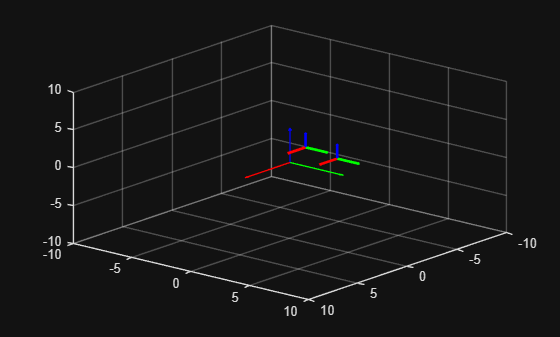

figure
hold on
grid on
view([130,30])
xlim([-10,10])
ylim([-10,10])
zlim([-10,10])

% X-Axis
quiver3(0,0,0,5,0,0, LineWidth=1,Color= "red")
% Y-Axis
quiver3(0,0,0,0,5,0, LineWidth=1,Color= "green" )
% Z-Axis
quiver3(0,0,0,0,0,5, LineWidth=1,Color= "blue" )

% 
% X-Axis
quiver3(Fnoa(1,4),Fnoa(2,4),Fnoa(3,4),Fnoa(1,1)*2,Fnoa(2,1)*2,Fnoa(3,1)*2, LineWidth=2,Color= "red" )
% Y-Axis
quiver3(Fnoa(1,4),Fnoa(2,4),Fnoa(3,4),Fnoa(1,2)*2,Fnoa(2,2)*2,Fnoa(3,2)*2, LineWidth=2,Color= "green" )
% Z-Axis
quiver3(Fnoa(1,4),Fnoa(2,4),Fnoa(3,4),Fnoa(1,3)*2,Fnoa(2,3)*2,Fnoa(3,3)*2, LineWidth=2,Color= "blue" )


% X-Axis
quiver3(Fnew(1,4),Fnew(2,4),Fnew(3,4),Fnew(1,1)*2,Fnew(2,1)*2,Fnew(3,1)*2, LineWidth=2,Color= "red" )
% Y-Axis
quiver3(Fnew(1,4),Fnew(2,4),Fnew(3,4),Fnew(1,2)*2,Fnew(2,2)*2,Fnew(3,2)*2, LineWidth=2,Color= "green" )
% Z-Axis
quiver3(Fnew(1,4),Fnew(2,4),Fnew(3,4),Fnew(1,3)*2,Fnew(2,3)*2,Fnew(3,3)*2, LineWidth=2,Color= "blue" )
hold off

# Part 2

theta = pi/2;
Rotation = [ cos(theta) 0 sin(theta) 0;
             0          1 0          0;
            -sin(theta) 0 cos(theta) 0;
             0          0 0          1]

Rotation =     0.0000         0    1.0000         0
         0    1.0000         0         0
   -1.0000         0    0.0000         0
         0         0         0    1.0000




Frot = Rotation * Fnoa

Frot =     0.0000         0    1.0000    4.0000
         0    1.0000         0    3.0000
   -1.0000         0    0.0000   -2.0000
         0         0         0    1.0000


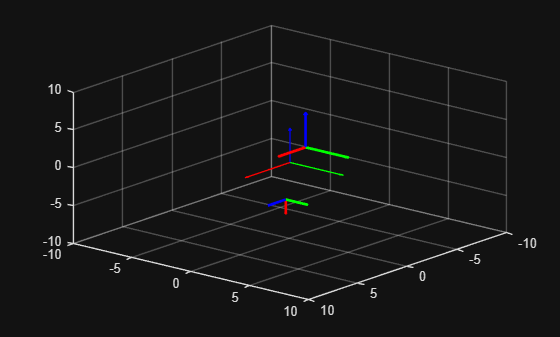



figure
hold on
grid on
view(130,30)
xlim([-10,10])
ylim([-10,10])
zlim([-10,10])

% X-Axis
quiver3(0,0,0,5,0,0, LineWidth=1,Color= "red")
% Y-Axis
quiver3(0,0,0,0,5,0, LineWidth=1,Color= "green" )
% Z-Axis
quiver3(0,0,0,0,0,5, LineWidth=1,Color= "blue" )

% 
% X-Axis
quiver3(Fnoa(1,4),Fnoa(2,4),Fnoa(3,4),Fnoa(1,4)+1,0,0, LineWidth=2,Color= "red" )
% Y-Axis
quiver3(Fnoa(1,4),Fnoa(2,4),Fnoa(3,4),0,Fnoa(2,4)+1,0, LineWidth=2,Color= "green" )
% Z-Axis
quiver3(Fnoa(1,4),Fnoa(2,4),Fnoa(3,4),0,0,Fnoa(3,4)+1, LineWidth=2,Color= "blue" )

% X-Axis
quiver3(Frot(1,4),Frot(2,4),Frot(3,4),Frot(1,1)*2,Frot(2,1)*2,Frot(3,1)*2, LineWidth=2,Color= "red" )
% Y-Axis
quiver3(Frot(1,4),Frot(2,4),Frot(3,4),Frot(1,2)*2,Frot(2,2)*2,Frot(3,2)*2, LineWidth=2,Color= "green" )
% Z-Axis
quiver3(Frot(1,4),Frot(2,4),Frot(3,4),Frot(1,3)*2,Frot(2,3)*2,Frot(3,3)*2, LineWidth=2,Color= "blue" )
hold off

# Part 3

F = [ 0  1  0  2;
      0  0 -1 -1;
      -1 0  0  3;
      0  0  0  1]

F =      0     1     0     2
     0     0    -1    -1
    -1     0     0     3
     0     0     0     1


F_T = TranslationTransformation(F, -2, 4, 1) 

F_T =      0     1     0     0
     0     0    -1     3
    -1     0     0     4
     0     0     0     1


F_R = RotationTransformation(F_T, "z", pi/4) 

F_R =          0    0.7071    0.7071   -2.1213
         0    0.7071   -0.7071    2.1213
   -1.0000         0         0    4.0000
         0         0         0    1.0000


F_R2 = RotationTransformation(F_R, "n", pi/6) 

F_R2 =          0    0.9659    0.2588   -2.1213
         0    0.2588   -0.9659    2.1213
   -1.0000         0         0    4.0000
         0         0         0    1.0000



function T = TranslationTransformation(F, dx, dy, dz)
    Translate = [ 1 0 0 dx;
                  0 1 0 dy;
                  0 0 1 dz;
                  0 0 0 1];
    T = Translate * F;

end

function T = RotationTransformation(F, axis, angle)
    if ismember(axis, ["x", "n"])
        Rotation = [ 1      0          0      0;
                     0 cos(angle) -sin(angle) 0;
                     0 sin(angle) cos(angle)  0;
                     0      0         0       1];
    elseif ismember(axis, ["y", "o"])
        Rotation = [ cos(angle) 0 sin(angle) 0;
                     0          1     0      0;
                    -sin(angle) 0 cos(angle) 0;
                     0          0     0      1];
    elseif ismember(axis, ["z", "a"])
        Rotation = [ cos(angle) -sin(angle) 0 0;
                     sin(angle) cos(angle)  0 0;
                         0          0       1 0 ;
                         0          0       0 1];
    else
        Rotation = [0 0 0 0;
                    0 0 0 0;
                    0 0 0 0;
                    0 0 0 0;];
    end
    if ismember(axis, ["x", "y", "z"])
        T = Rotation * F;
    elseif ismember(axis, ["n", "o", "a"])
        T = F * Rotation;
    else
        T = [0 0 0 0;
             0 0 0 0;
             0 0 0 0;
             0 0 0 0;];
    end


end


# Part 4

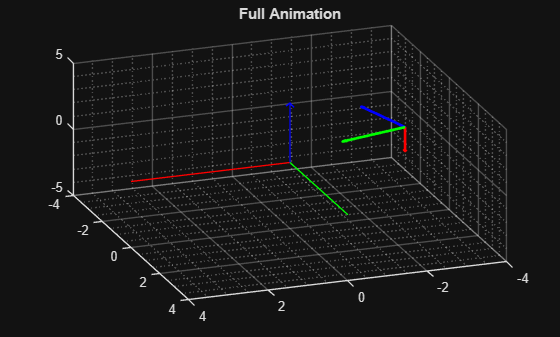

x = 1;
graph_step = 40;
steps = 3;
Step_Size = graph_step * steps;
for i = 1:1:Step_Size
    cla
    if i == 1
        fig = figure(1);
        grid on
        grid minor
        view([160 40]);
        xlim([-4,4])
        ylim([-4,4])
        zlim([-5,5])
        title('Full Animation');
    end
    hold on

    if i <= graph_step
        index = i * 1/graph_step;
        F_loop = TranslationTransformation(F, -2*index, 4*index, 1*index);
        if i == graph_step
            F = F_loop;
        end

    elseif i <= graph_step *2 
        index = (i-graph_step) * 1/graph_step;
        F_loop = RotationTransformation(F, "z", pi/4*index) ;
        if i == graph_step *2
            F = F_loop;
        end

    elseif i <= graph_step *3 
        index = (i-graph_step*2) * 1/graph_step;
        F_loop = RotationTransformation(F, "n", pi/6* index);
        if i == graph_step*3
            F = F_loop;
        end
    else

    end


    % X-Axis
    quiver3(0,0,0,5,0,0, LineWidth=1,Color= "red")
    % Y-Axis
    quiver3(0,0,0,0,5,0, LineWidth=1,Color= "green" )
    % Z-Axis
    quiver3(0,0,0,0,0,5, LineWidth=1,Color= "blue" )
    
    % X-Axis
    quiver3(F_loop(1,4),F_loop(2,4),F_loop(3,4),F_loop(1,1)*2,F_loop(2,1)*2,F_loop(3,1)*2, LineWidth=2,Color= "red" )
    % Y-Axis
    quiver3(F_loop(1,4),F_loop(2,4),F_loop(3,4),F_loop(1,2)*2,F_loop(2,2)*2,F_loop(3,2)*2, LineWidth=2,Color= "green" )
    % Z-Axis
    quiver3(F_loop(1,4),F_loop(2,4),F_loop(3,4),F_loop(1,3)*2,F_loop(2,3)*2,F_loop(3,3)*2, LineWidth=2,Color= "blue" )
    hold off


    drawnow ('limitrate'); 
    frame = getframe(fig);
    im{x} = frame2im(frame);
    x = x + 1;
end